#### **データの読み込み**

path="D:\Project\Data\Sumiyosi";
dir=get_dir(path);
csv_path=path +"\"+ dir(1).name
Honkawa1 = csvread(csv_path);

Index in position 3 exceeds array bounds. Index must not exceed 1.

img_seq=imcon(Honkawa1);
norm_seq=nd(img_seq,3);

#### **前処理**

norm_clean_BW=clean_image(norm_seq,0,1);
norm_clean_seq=(norm_clean_BW>0.26).*norm_clean_BW;
sample_seq=norm_clean_seq(:,:,1000:1500);

clear mem

num=0;
l=0;
height=132;
width=70;
mem(200).center=[];
mem(200).seq=[];
N1=[];
N2=[];

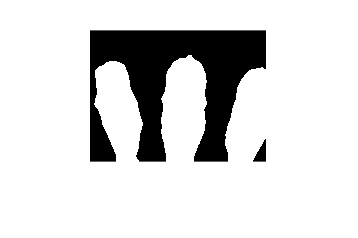

for i=1:500
    A=W(:,:,i);
    BW=imbinarize(A);
    BW2 = bwareaopen(BW, 3000);
    N1(:,:,i)=BW2;
end


for i=1:500
    A=W(:,:,i);
    BW=imbinarize(A);
    BW2 = bwareaopen(BW, 2000);
    
    s = regionprops(BW2,'centroid');
    centroids = cat(1, s.Centroid);
    a=size(centroids,1); 
    
    
    if sum(BW2(:,1))>0
        N1(i)=1;
    else
        N1(i)=0;
    end
    
    
    if sum(BW2(:,172))>0
        N2(i)=1;
    else
        N2(i)=0;
    end
    
    
    if i>1 && N1(i-1)-N1(i)==-1
        num=num+1;
        l=l+1;
        
    elseif i>1 && N2(i-1)-N2(i)==1
        num=num-1;
    end
    
    
    if num>0
        for n=1:num
           t(n).center=comp(round(centroids(n,1)-35));
        end    
        
        for j=1:num
            mem(l+1-j).center=[mem(l+1-j).center t(j).center];
            x=t(j).center;
            lab=(bwlabeln(BW2)==j);
            I=A(1:height,x:width+x).*lab(1:height,x:width+x);
            mem(l+1-j).seq=cat(3,mem(l+1-j).seq,I);
        end
        
        if a(1)>0
            th=centroids(a(1),1);
        end
    end
end

 m=mean(mem(1).seq,"all");

me=0;
st=0;

for i=1:25
    m=mean(mem2(i).seq,"all");
    s=var(mem2(i).seq,0,"all");
    me=me+m;
    st=st+s;
end
me=me/25 %0.143

me = 0.1433

st=sqrt(st/24) %0.166

st = 0.1644

clear mem2
mem2(200).seq=[];
for i=1:l
    seq=mem(i).seq;
    center_frame=round(size(seq)/2);
    mem2(i).seq=seq(:,:,center_frame(3)-3:center_frame(3)+3);
end

for i=1:27
csvwrite(i+".csv",mem2(i).seq);
end